# Power Split Drive Unit Model

Copyright 2021 The Mathworks, Inc.

## Open the Model

mdl = "PowerSplitDriveUnitBasic_test_harness";
if not(bdIsLoaded(mdl)), open_system(mdl); end

PowerSplitDriveUnitBasic_setup

## Load Inputs to Workspace

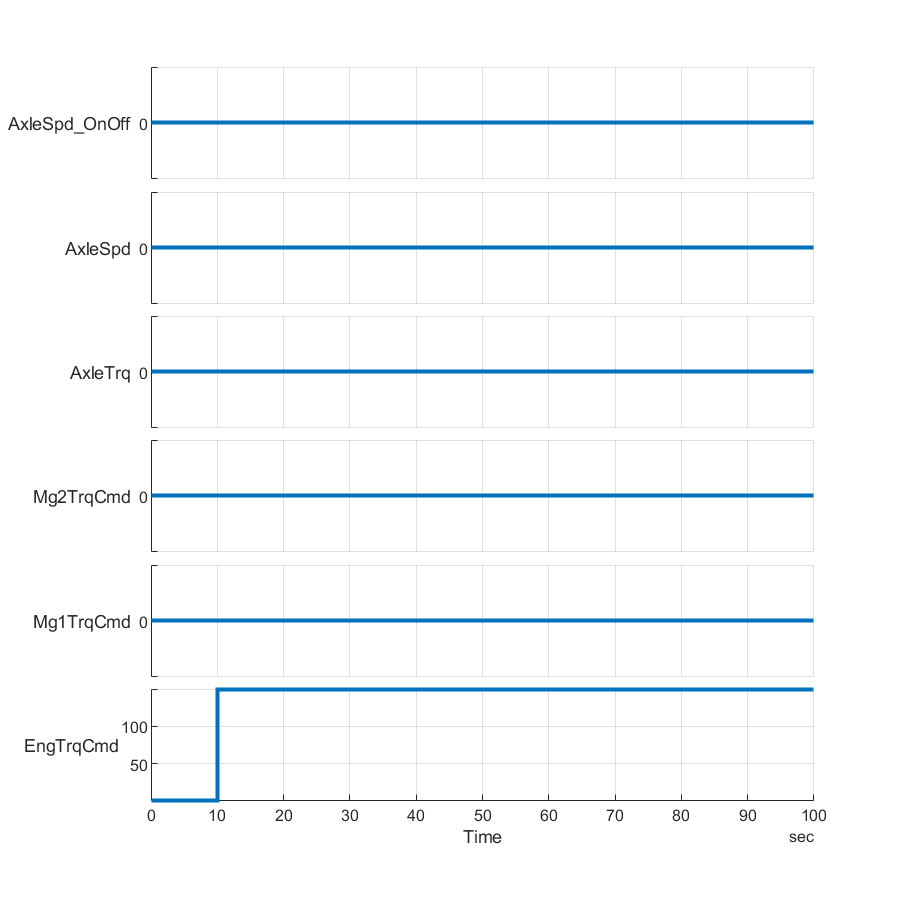

fig = figure;
% fig.Position(3:4) = [400 300];
[inputSignals_PSDU, inputBus_PSDU, t_end] = ...
  PowerSplitDriveUnitBasic_inputs( ...
    "PlotParent",fig, "InputPattern","drive_engine" );

## Run Simulation

% Override initial conditions
initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override parameters

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

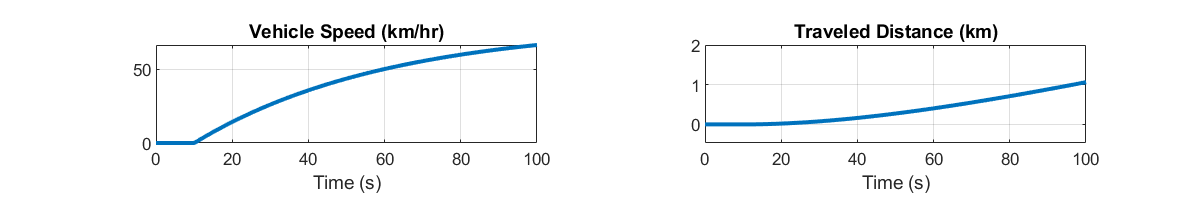

fig = figure;
fig.Position(3:4) = [800 200];
PowerSplitDriveUnitBasic_plot_vehicle("Dataset",out.logsout, "PlotParent",fig);

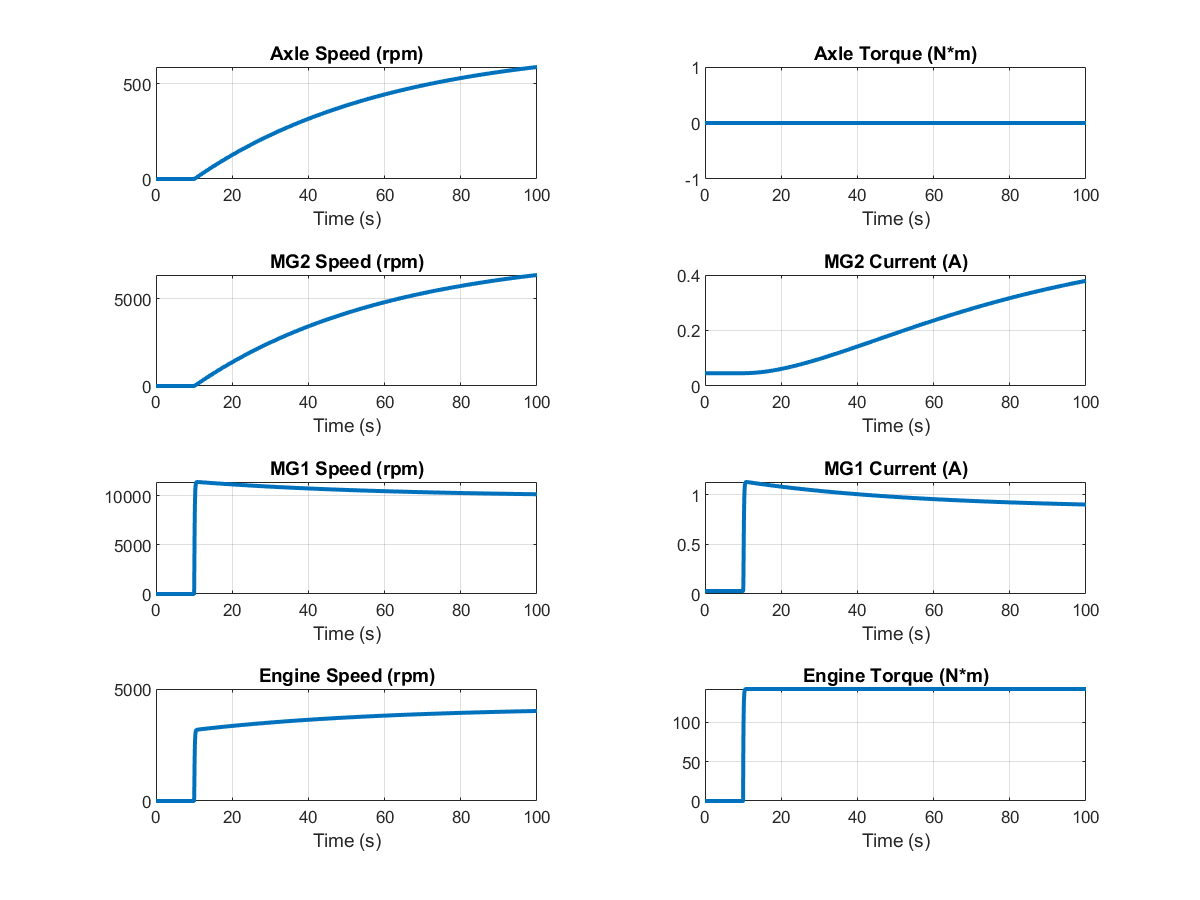

fig = figure;
fig.Position(3:4) = [800 600];
PowerSplitDriveUnitBasic_plot_psdu("Dataset",out.logsout, "PlotParent",fig);

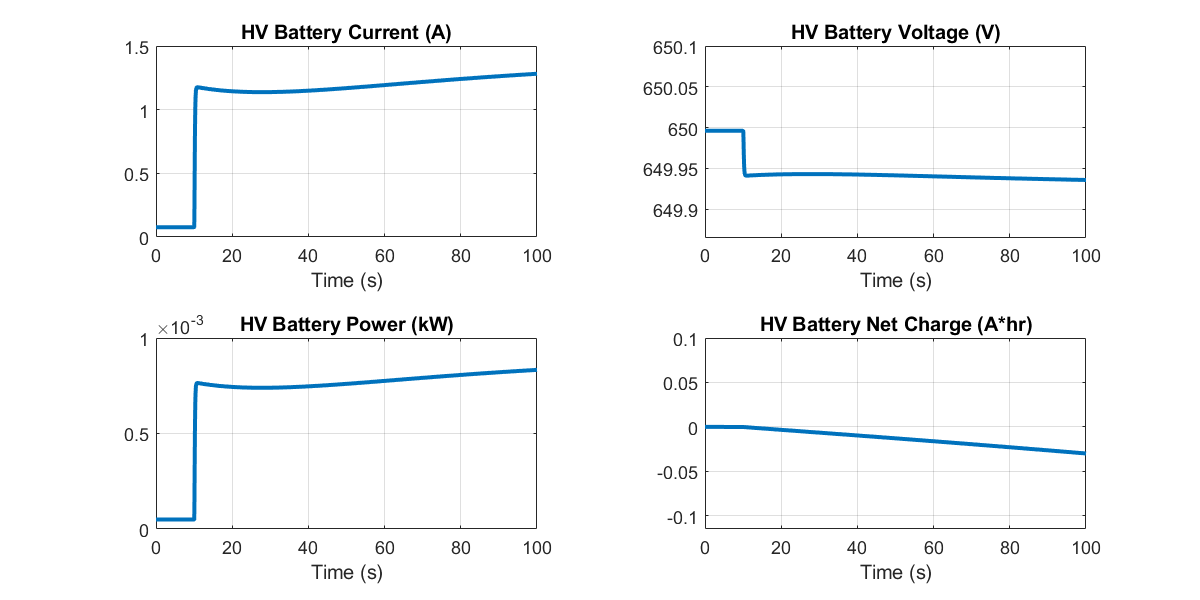

fig = figure;
fig.Position(3:4) = [800 400];
PowerSplitDriveUnitBasic_plot_hvbattery("Dataset",out.logsout, "PlotParent",fig);